# Mid-Plate Pose Optimization via Genetic Algorithm (Power-Minimizing Objective)

REQUIRES: Global Optimization Toolbox (for ga()).

Objective: minimize |Power| = |wrench' * J * deltaL|, where J is the 6x12 hybrid two-segment Jacobian and deltaL is the 12-vector of limb-length displacements (dt fixed, so rho_dot is approximated by rho). Implemented ga() with MATLAB's STANDARD/DEFAULT operators.

## Section 0: Problem Setup (shared by both blocks)

clear; clc;

point   = [0, 0, 3, 0, 0, 0];                       % end-effector global pose [x y z roll pitch yaw]
lowLim  = [-1, -1, 0.5, -pi/6, -pi/6, -pi/4];       % mid-plate pose lower bounds
highLim = [ 1,  1, 2.0,  pi/6,  pi/6,  pi/4];       % mid-plate pose upper bounds
radii      = [0.5, 0.45, 0.4];                       % [R_base, R_midplate, R_platform]
wrench     = [0, 0, -50, 0, 0, 0];                  % fixed end-effector wrench [Fx Fy Fz Mx My Mz]
seg2Weight = [0, 0, -20, 0, 0, 0];                  % weight of segment 2 (+ payload), acting on the mid-plate only
nvars      = 6;

% Reference (home) leg lengths: physically, each actuator's displacement
% is measured FROM here, not from zero. Below assumes home = mid-plate
% centered, untilted, at mid-travel height -- replace with your actual
% retracted/home configuration.
homePose            = [0, 0, (lowLim(3) + highLim(3)) / 2, 0, 0, 0];
[links1Home, ~, ~]  = formulatedIKP(homePose, radii(1:2));
homePointLocal      = global2local(point, homePose);
[links2Home, ~, ~]  = formulatedIKP(homePointLocal, radii(2:3));
lHome               = [links1Home, links2Home];     % 1x12 reference leg lengths

PopulationSize = 1000;
MaxGenerations = 500;
Pcross         = 0.8;   % crossover rate

% Objective: Minimize gross actuator power, computed from the TRUE joint
% displacement deltaL = l - lHome (not the raw leg length l), so poses
% aren't rewarded merely for shrinking legs toward an arbitrary origin.
objFun = @(pose) objectiveIKP(pose, radii, point, wrench, seg2Weight, lHome);

## Block A: ga() with Standard / Default Operators

Only problem-scale settings are specified; creation, selection, crossover, and mutation functions are left at MATLAB's defaults.

optionsDefault = optimoptions('ga', ...
    'PopulationSize',   PopulationSize, ...
    'MaxGenerations',   MaxGenerations, ...
    'CrossoverFraction', Pcross, ...
    'MaxTime', 5*60, ...                
    'PlotFcn', {@gaplotbestf,@gaplotstopping}, ...
    'CrossoverFcn', @crossoverintermediate, ...  % Better for continuous problems
    'FunctionTolerance',1e-5, ...
    'Display', 'off');

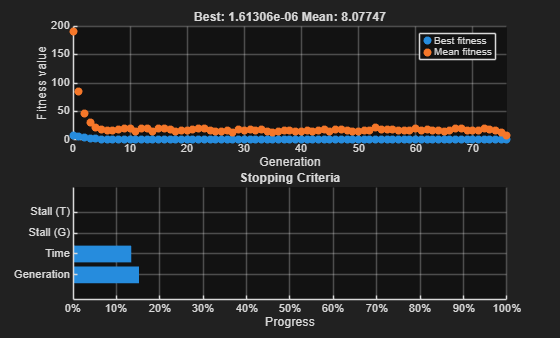

rng(1);  
[poseDefault, grossPowerDefault] = ga(objFun, nvars, [], [], [], [], lowLim, highLim, [], optionsDefault);


[~, links1Default, links2Default, netPowerDefault] = objectiveIKP(poseDefault, radii, point, wrench, seg2Weight, lHome);

fprintf('mid-plate pose:   %s\n', mat2str(round(poseDefault, 4)));

mid-plate pose:   [0 0 1.25 0 0 0]


fprintf('stage-1 links:    %s\n', mat2str(round(links1Default, 4)));

stage-1 links:    [1.3379 1.3379 1.3379 1.3379 1.3379 1.3379]


fprintf('stage-2 links:    %s\n', mat2str(round(links2Default, 4)));

stage-2 links:    [1.8014 1.8014 1.8014 1.8014 1.8014 1.8014]


fprintf('net power (signed):     %.4f\n', netPowerDefault);

net power (signed):     -0.0000


gross power (minimized): 0.0000



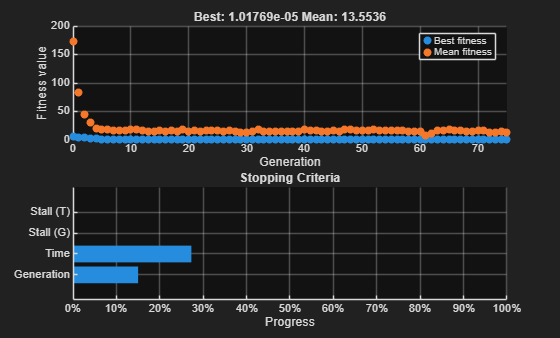

--- Block A: MATLAB default ga() operators ---


mid-plate pose:   [0 0 1.25 0 0 0]


stage-1 links:    [1.3463 1.3463 1.3463 1.3463 1.3463 1.3463]


stage-2 links:    [1.82 1.82 1.82 1.82 1.82 1.82]


net power (signed):     -0.0000


gross power (minimized): 0.0000



fprintf('gross power (minimized): %.4f\n\n', grossPowerDefault);

opts = optimoptions('fmincon', 'Display', 'off');
[posePolished, powerPolished] = fmincon(objFun, poseDefault, [], [], [], [], lowLim, highLim, [], opts);
fprintf('GA power: %.6f  ->  polished power: %.6f\n', grossPowerDefault, powerPolished);

GA power: 0.000002  ->  polished power: 0.000001


fprintf('GA pose: %s', num2str(poseDefault));

GA pose: -5.0529e-09  1.0848e-08        1.25 -3.4161e-08  1.6052e-08  -5.225e-08

fprintf('polished pose: %s', num2str(posePolished));

polished pose: 7.427e-10  4.4378e-09        1.25 -2.8559e-08  1.1466e-08 -4.6863e-08

eps_ = 1e-4;
grad = zeros(1,6);
for k = 1:6
    poseP = poseDefault; poseP(k) = poseP(k) + eps_;
    poseM = poseDefault; poseM(k) = poseM(k) - eps_;
    grad(k) = (objFun(poseP) - objFun(poseM)) / (2*eps_);
end
disp(grad)   % should be ~0 in directions where the bound isn't active

    0.0036   -0.0039    0.0115   -0.0114    0.0051   -0.0080



% --- Particle Swarm (population-based, gradient-free) ---
psoOpts = optimoptions('particleswarm', 'SwarmSize', 200, 'MaxIterations', 500, 'Display', 'off');
[posePSO, grossPowerPSO] = particleswarm(objFun, nvars, lowLim, highLim, psoOpts);
[~, links1PSO, links2PSO, netPowerPSO] = objectiveIKP(posePSO, radii, point, wrench, seg2Weight, lHome);

% --- Pattern Search (deterministic direct search, seeded from the GA result) ---
psOpts = optimoptions('patternsearch', 'Display', 'off', 'MaxIterations', 2000);
[posePS, grossPowerPS] = patternsearch(objFun, poseDefault, [], [], [], [], lowLim, highLim, [], psOpts);
[~, links1PS, links2PS, netPowerPS] = objectiveIKP(posePS, radii, point, wrench, seg2Weight, lHome);

% --- Simulated Annealing (tolerates uphill moves, checks for bound-sticking) ---
saOpts = optimoptions('simulannealbnd', 'MaxIterations', 5000, 'Display', 'off');
[poseSA, grossPowerSA] = simulannealbnd(objFun, poseDefault, lowLim, highLim, saOpts);
[~, links1SA, links2SA, netPowerSA] = objectiveIKP(poseSA, radii, point, wrench, seg2Weight, lHome);

fprintf('--- Alternative Optimizer Validation ---\n');

--- Alternative Optimizer Validation ---


fprintf('%-16s %10s %10s %10s %10s %10s %10s\n', '', 'x', 'y', 'z', 'roll', 'pitch', 'yaw');

                          x          y          z       roll      pitch        yaw


fprintf('%-16s %s\n', 'GA (custom):', mat2str(round(poseDefault, 4)));

GA (custom):     [0 0 1.25 0 0 0]


fprintf('%-16s %s\n', 'ParticleSwarm:', mat2str(round(posePSO, 4)));

ParticleSwarm:   [0 0 1.25 0 0 0]


fprintf('%-16s %s\n', 'PatternSearch:', mat2str(round(posePS, 4)));

PatternSearch:   [0 0 1.25 0 0 0]


fprintf('%-16s %s\n\n', 'SimAnneal:', mat2str(round(poseSA, 4)));

SimAnneal:       [0 0 1.25 0 0 0]




fprintf('%-16s %14s %14s\n', '', 'Gross power', 'Net power');

                    Gross power      Net power


fprintf('%-16s %14.6f %14.6f\n', 'GA (custom):', grossPowerDefault, netPowerDefault);

GA (custom):           0.000002      -0.000000


fprintf('%-16s %14.6f %14.6f\n', 'ParticleSwarm:', grossPowerPSO, netPowerPSO);

ParticleSwarm:         0.000000      -0.000000


fprintf('%-16s %14.6f %14.6f\n', 'PatternSearch:', grossPowerPS, netPowerPS);

PatternSearch:         0.000002      -0.000000


fprintf('%-16s %14.6f %14.6f\n\n', 'SimAnneal:', grossPowerSA, netPowerSA);

SimAnneal:             0.000002      -0.000000



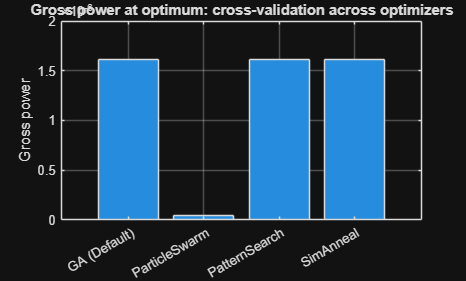

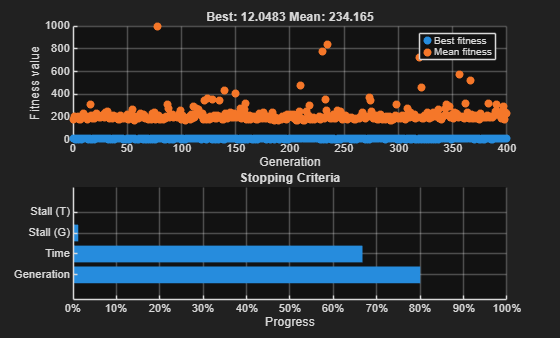

--- Block B: Custom operators (replicating original Python GA) ---


mid-plate pose:   [0.15 -0.05 1.2 0.1264 0.1764 -0.6854]


stage-1 links:    [1.4642 1.3104 1.1807 1.521 1.3011 1.1796]


stage-2 links:    [1.7401 1.9612 1.8652 1.771 1.9335 2.0554]


net power (signed):     4.9314


gross power (minimized): 12.0483



=== Comparison ===


                          Default ga()    Custom GA


Gross power (W)                 0.0000      12.0483


Net power (W)                  -0.0000       4.9314


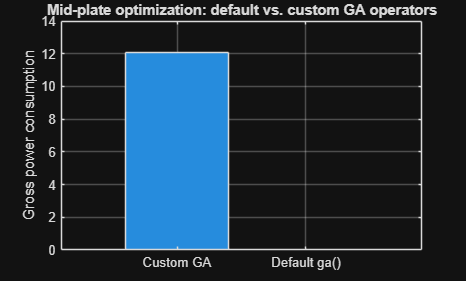


figure('Name', 'Optimizer Cross-Validation');
methodNames = categorical({'GA (Default)', 'ParticleSwarm', 'PatternSearch', 'SimAnneal'});
methodNames = reordercats(methodNames, {'GA (Default)', 'ParticleSwarm', 'PatternSearch', 'SimAnneal'});
grossVals = [grossPowerDefault, grossPowerPSO, grossPowerPS, grossPowerSA];
bar(methodNames, grossVals);
ylabel('Gross power');
title('Gross power at optimum: cross-validation across optimizers');
grid on;

## Power Sensitivity Analysis

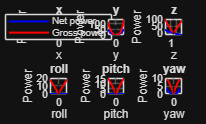

basePose = poseDefault;  
nSweep   = 41;
varNames = {'x', 'y', 'z', 'roll', 'pitch', 'yaw'};

netPowerSweep   = zeros(6, nSweep);
grossPowerSweep = zeros(6, nSweep);
sweepGrid       = zeros(6, nSweep);

for k = 1:6
    sweepGrid(k, :) = linspace(lowLim(k), highLim(k), nSweep);
    for j = 1:nSweep
        testPose = basePose;
        testPose(k) = sweepGrid(k, j);
        [grossPowerSweep(k, j), ~, ~, netPowerSweep(k, j)] = ...
            objectiveIKP(testPose, radii, point, wrench, seg2Weight, lHome);
    end
end

figure('Name', 'Power Sensitivity to Mid-Plate Pose Variables');
for k = 1:6
    subplot(2, 3, k);
    plot(sweepGrid(k, :), netPowerSweep(k, :), 'b-', 'LineWidth', 1.5); hold on;
    plot(sweepGrid(k, :), grossPowerSweep(k, :), 'r-', 'LineWidth', 1.5);
    xline(basePose(k), 'k--', 'HandleVisibility', 'off');
    xlabel(varNames{k});
    ylabel('Power');
    title(varNames{k});
    grid on;
    if k == 1
        legend('Net power', 'Gross power', 'Location', 'best');
    end
end

## Local Functions

function [grossPower, links1, links2, netPower] = objectiveIKP(pose, radii, point, wrench, seg2Weight, lHome)
% netPower   = wrench' * (GJ2*deltaL) + seg2Weight' * (GJ1*deltaL1)   [diagnostic only]
% grossPower = sum(|tau_i * deltaL_i|) over all legs                 [minimize this]
% tau = J' * F is the min-norm actuator-force solution for a given task wrench.
% Using |tau.*deltaL| instead of the signed dot product prevents legs that
% push/pull against each other (net work = 0) from being scored as "free".
% deltaL = l - lHome is the TRUE joint-space displacement from the actuators'
% home configuration -- using raw l would let a pose "cheat" by shrinking
% legs toward an arbitrary origin rather than truly displacing less.
    [links1, sHat1, bRot1] = formulatedIKP(pose, radii(1:2));
    endPointLocal = global2local(point, pose);
    [links2, sHat2, bRot2] = formulatedIKP(endPointLocal, radii(2:3));

    GJ1 = localJacobian(sHat1, bRot1);   % segment 1's base frame IS the global frame
    J2  = localJacobian(sHat2, bRot2);   % segment 2's Jacobian in its own base frame (the mid-plate)

    Q1 = rotationMatrix(pose(4:6));      % mid-plate orientation, global frame
    p1 = pose(1:3)';                     % mid-plate position, global frame
    p2 = point(1:3)';                    % fixed goal position of the final e-e, global frame
    r  = p2 - p1;

    % Rigid-body velocity transport: v2 = v1 + omega x (p2 - p1)
    V1 = [eye(3), -skewMat(r); zeros(3), eye(3)];
    W1 = [Q1, zeros(3); zeros(3), Q1];

    GJ2 = [V1 * GJ1, W1 * J2];           % 6x12, eqs. (20)-(23)

    deltaL  = [links1, links2]' - lHome';  % 12x1 TRUE joint-space displacement
    deltaL1 = deltaL(1:6);                 % segment-1 legs only, for the seg2-weight term

    % --- diagnostic: signed net power ---
    powerTip      = wrench * (GJ2 * deltaL);
    powerSeg1Load = seg2Weight * (GJ1 * deltaL1);
    netPower      = powerTip + powerSeg1Load;

    % --- objective: gross (actuator) power ---
    tauTip  = GJ2' * wrench';             % 12x1
    tauSeg1 = GJ1' * seg2Weight';         % 6x1

    grossPowerTip  = sum(abs(tauTip .* deltaL));
    grossPowerSeg1 = sum(abs(tauSeg1 .* deltaL1));
    grossPower     = grossPowerTip + grossPowerSeg1;
end

function [l, sHat, bRot] = formulatedIKP(pose, R)
    p     = pose(1:3)';
    theta = pose(4:6);
    deg2rad = pi / 180;

    a = zeros(3, 3);  
    b = zeros(3, 3);  

    a(:, 1) = R(1) * [0; 1; 0];
    a(:, 2) = R(1) * [cos(210 * deg2rad); sin(210 * deg2rad); 0];
    a(:, 3) = R(1) * [cos(330 * deg2rad); sin(330 * deg2rad); 0];

    b(:, 1) = R(2) * [0; -1; 0];
    b(:, 2) = R(2) * [cos(30 * deg2rad); sin(30 * deg2rad); 0];
    b(:, 3) = R(2) * [cos(150 * deg2rad); sin(150 * deg2rad); 0];

    Q = rotationMatrix(theta);

    aIdx = [1, 1, 2, 2, 3, 3];
    bIdx = [2, 3, 1, 3, 1, 2];

    l    = zeros(1, 6);
    sHat = zeros(6, 3);  % unit vector of each limb (s_hat_i in eq. 5)
    bRot = zeros(6, 3);  % rotated e-e attach point (Q*b_i, used for b_i x s_hat_i)

    for i = 1:6
        bRotI = Q * b(:, bIdx(i));
        diffI = p + bRotI - a(:, aIdx(i));
        lenI  = norm(diffI);
        l(i)      = lenI;
        sHat(i,:) = (diffI / lenI)';
        bRot(i,:) = bRotI';
    end
end

function J = localJacobian(sHat, bRot)
% Segment Jacobian per eq. (5) of the kinematics note: stack rows
% [s_hat_i^T, (b_i x s_hat_i)^T] for the 6 limbs, then invert. Returns
% the 6x6 matrix (i-1)J_i such that t = J * rho_dot (eq. 6).
    A = zeros(6, 6);
    for i = 1:6
        A(i, 1:3) = sHat(i, :);
        A(i, 4:6) = cross(bRot(i, :), sHat(i, :));
    end
    J = inv(A);
end

function S = skewMat(v)
    S = [0, -v(3), v(2); v(3), 0, -v(1); -v(2), v(1), 0];
end

function Q = rotationMatrix(theta)
% rotation_matrix (Euler Z-Y-X).
% theta = [roll(x), pitch(y), yaw(z)]
    Q = [ ...
        cos(theta(3)) * cos(theta(2)), ...
        cos(theta(3)) * sin(theta(2)) * sin(theta(1)) - sin(theta(3)) * cos(theta(1)), ...
        cos(theta(3)) * sin(theta(2)) * cos(theta(1)) + sin(theta(3)) * sin(theta(1)); ...
        ...
        sin(theta(3)) * cos(theta(2)), ...
        sin(theta(3)) * sin(theta(2)) * sin(theta(1)) + cos(theta(3)) * cos(theta(1)), ...
        sin(theta(3)) * sin(theta(2)) * cos(theta(1)) - cos(theta(3)) * sin(theta(1)); ...
        ...
        -sin(theta(2)), ...
        cos(theta(2)) * sin(theta(1)), ...
        cos(theta(2)) * cos(theta(1))];
end

function T = transformationMatrix(pose)
    pose = pose(:)';
    P  = pose(1:3)';
    th = pose(4:6);
    R  = rotationMatrix(th);
    T  = [R, P; 0, 0, 0, 1];
end

function angles = reverseRotation(R)
% Returns [roll(x), pitch(y), yaw(z)].
    beta  = asin(-R(3, 1));
    gamma = atan2(R(3, 2) / cos(beta), R(3, 3) / cos(beta));
    alpha = atan2(R(2, 1) / cos(beta), R(1, 1) / cos(beta));
    angles = [gamma, beta, alpha];
end

function localPoint = global2local(globalPoint, midPlate)
    T  = transformationMatrix(globalPoint);
    T1 = transformationMatrix(midPlate);
    T2 = T1 \ T;
    localPoint = [T2(1:3, 4)', reverseRotation(T2(1:3, 1:3))];
end

function comparison (point, wrench, seg2Weight, radii, lHome, lowLim, highLim, nvars, optionsDefault)
    objFun  = @(pose) objectiveIKP(pose, radii, point, wrench, seg2Weight, lHome);
    rng(1);  
    
    [poseDefault, grossPowerDefault] = ga(objFun, nvars, [], [], [], [], lowLim, highLim, [], optionsDefault);
    [~, links1Default, links2Default, netPowerDefault] = objectiveIKP(poseDefault, radii, point, wrench, seg2Weight, lHome);
    
    % --- Particle Swarm (population-based, gradient-free) ---
    psoOpts = optimoptions('particleswarm', 'SwarmSize', 200, 'MaxIterations', 500, 'Display', 'off');
    [posePSO, grossPowerPSO] = particleswarm(objFun, nvars, lowLim, highLim, psoOpts);
    [~, links1PSO, links2PSO, netPowerPSO] = objectiveIKP(posePSO, radii, point, wrench, seg2Weight, lHome);
    
    % --- Pattern Search (deterministic direct search, seeded from the GA result) ---
    psOpts = optimoptions('patternsearch', 'Display', 'off', 'MaxIterations', 2000);
    [posePS, grossPowerPS] = patternsearch(objFun, poseDefault, [], [], [], [], lowLim, highLim, [], psOpts);
    [~, links1PS, links2PS, netPowerPS] = objectiveIKP(posePS, radii, point, wrench, seg2Weight, lHome);
    
    % --- Simulated Annealing (tolerates uphill moves, checks for bound-sticking) ---
    saOpts = optimoptions('simulannealbnd', 'MaxIterations', 5000, 'Display', 'off');
    [poseSA, grossPowerSA] = simulannealbnd(objFun, posePSO, lowLim, highLim, saOpts);
    [~, links1SA, links2SA, netPowerSA] = objectiveIKP(poseSA, radii, point, wrench, seg2Weight, lHome);
    
    fprintf('mid-plate pose:   %s\n', mat2str(round(poseDefault, 4)));
    fprintf('stage-1 links:    %s\n', mat2str(round(links1Default, 4)));
    fprintf('stage-2 links:    %s\n', mat2str(round(links2Default, 4)));
    fprintf('gross power (minimized): %.4f\n\n', grossPowerDefault);
    
    fprintf('--- Alternative Optimizer Validation ---\n');
    fprintf('%-16s %10s %10s %10s %10s %10s %10s\n', '', 'x', 'y', 'z', 'roll', 'pitch', 'yaw');
    fprintf('%-16s %s\n', 'GA (custom):', mat2str(round(poseDefault, 4)));
    fprintf('%-16s %s\n', 'ParticleSwarm:', mat2str(round(posePSO, 4)));
    fprintf('%-16s %s\n', 'PatternSearch:', mat2str(round(posePS, 4)));
    fprintf('%-16s %s\n\n', 'SimAnneal:', mat2str(round(poseSA, 4)));
    
    fprintf('%-16s %14s %14s\n', '', 'Gross power', 'Net power');
    fprintf('%-16s %14.6f %14.6f\n', 'GA (custom):', grossPowerDefault, netPowerDefault);
    fprintf('%-16s %14.6f %14.6f\n', 'ParticleSwarm:', grossPowerPSO, netPowerPSO);
    fprintf('%-16s %14.6f %14.6f\n', 'PatternSearch:', grossPowerPS, netPowerPS);
    fprintf('%-16s %14.6f %14.6f\n\n', 'SimAnneal:', grossPowerSA, netPowerSA);
    
    figure('Name', 'Optimizer Cross-Validation');
    methodNames = categorical({'GA (Default)', 'ParticleSwarm', 'PatternSearch', 'SimAnneal'});
    methodNames = reordercats(methodNames, {'GA (Default)', 'ParticleSwarm', 'PatternSearch', 'SimAnneal'});
    grossVals = [grossPowerDefault, grossPowerPSO, grossPowerPS, grossPowerSA];
    bar(methodNames, grossVals);
    ylabel('Gross power');
    title('Gross power at optimum: cross-validation across optimizers');
    grid on;
end

## Test Case 2

mid-plate pose:   [-0.649 1 0.5 -0.5236 -0.5236 -0.5727]
stage-1 links:    [0.7778 1.1478 1.3123 1.6175 1.8373 1.4881]
stage-2 links:    [2.9792 2.8982 3.1664 2.831 2.5134 2.4199]
gross power (minimized): 0.0000

--- Alternative Optimizer Validation ---
                          x          y          z       roll      pitch        yaw
GA (custom):     [-0.649 1 0.5 -0.5236 -0.5236 -0.5727]
ParticleSwarm:   [-0.3804 -0.2894 1.2828 -0.0394 -0.2415 0.7814]
PatternSearch:   [-0.649 1 0.5 -0.5236 -0.5236 -0.5727]
SimAnneal:       [-0.3804 -0.2894 1.2828 -0.0394 -0.2415 0.7814]

                    Gross power      Net power
GA (custom):           0.000000       0.000000
ParticleSwarm:         0.000000       0.000000
PatternSearch:         0.000000       0.000000
SimAnneal:             0.000000       0.000000



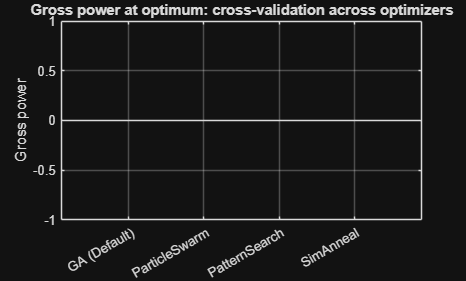

point   = [0, 0, 3, 0, 0, 0];   
wrench  = [0, 0, 0, 0, 0, 0];   
seg2Weight = [0, 0, 0, 0, 0, 0]; 
comparison(point, wrench, seg2Weight, radii, lHome, lowLim, highLim, nvars, optionsDefault);

## Test Case 3

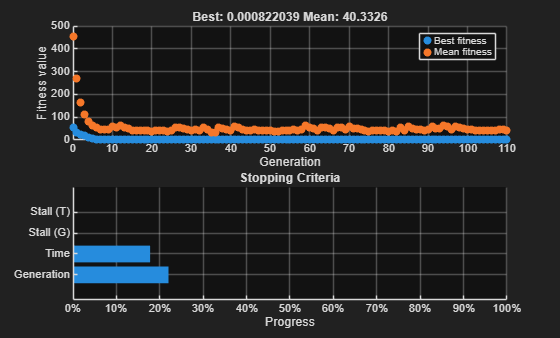

mid-plate pose:   [0 0 1.25 0 0 0]
stage-1 links:    [1.3379 1.3379 1.3379 1.3379 1.3379 1.3379]
stage-2 links:    [1.8014 1.8014 1.8014 1.8014 1.8014 1.8014]
gross power (minimized): 0.0008

--- Alternative Optimizer Validation ---
                          x          y          z       roll      pitch        yaw
GA (custom):     [0 0 1.25 0 0 0]
ParticleSwarm:   [0 0 1.25 0 0 0]
PatternSearch:   [0 0 1.25 0 0 0]
SimAnneal:       [0 0 1.25 0 0 0]

                    Gross power      Net power
GA (custom):           0.000822      -0.000016
ParticleSwarm:         0.000000      -0.000000
PatternSearch:         0.000581      -0.000016
SimAnneal:             0.000000       0.000000



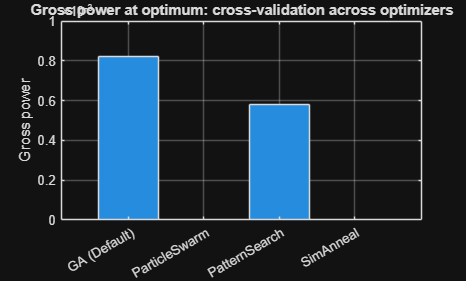

point   = [0, 0, 3, 0, 0, 0];   
wrench  = [0, 0, 0, 0, 0, 40];   
seg2Weight = [0, 0, -20, 0, 0, 0]; 
comparison(point, wrench, seg2Weight, radii, lHome, lowLim, highLim, nvars, optionsDefault);

## Test Case 4

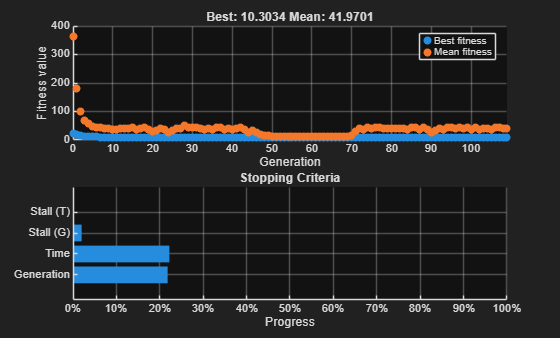

mid-plate pose:   [-0.0245 0.3997 1.2795 -0.0255 -0.0144 -0.0607]
stage-1 links:    [1.3379 1.3379 1.3609 1.5542 1.3936 1.5373]
stage-2 links:    [1.8003 1.8014 1.8174 1.9921 1.8015 2.0051]
gross power (minimized): 10.3034

--- Alternative Optimizer Validation ---
                          x          y          z       roll      pitch        yaw
GA (custom):     [-0.0245 0.3997 1.2795 -0.0255 -0.0144 -0.0607]
ParticleSwarm:   [-0.0346 0.3888 1.2797 -0.022 -0.0203 -0.0766]
PatternSearch:   [-0.0245 0.3997 1.2795 -0.0256 -0.0144 -0.0599]
SimAnneal:       [-0.0346 0.3888 1.2797 -0.022 -0.0203 -0.0766]

                    Gross power      Net power
GA (custom):          10.303411       9.485312
ParticleSwarm:        10.315076       9.430213
PatternSearch:        10.302643       9.485349
SimAnneal:            10.315076       9.430213



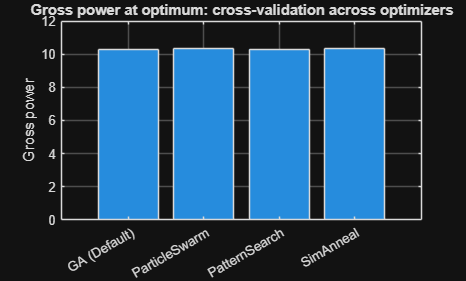

point   = [0, 1, 3, 0, 0, 0];   
wrench  = [0, 0, -50, 0, 0, 0];   
seg2Weight = [0, 0, -20, 0, 0, 0]; 
comparison(point, wrench, seg2Weight, radii, lHome, lowLim, highLim, nvars, optionsDefault);

## Test Case 5A

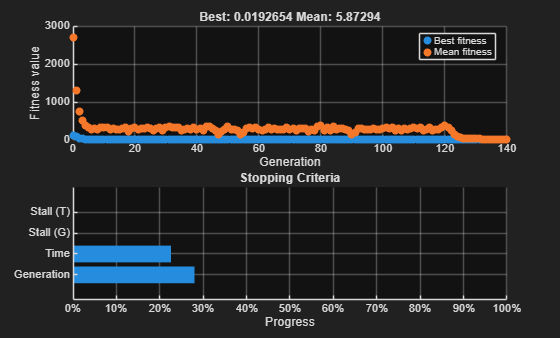

mid-plate pose:   [0 0 1.25 0 0 0.0001]
stage-1 links:    [1.3379 1.3379 1.3379 1.3379 1.3379 1.338]
stage-2 links:    [1.8014 1.8014 1.8014 1.8014 1.8014 1.8013]
gross power (minimized): 0.0193

--- Alternative Optimizer Validation ---
                          x          y          z       roll      pitch        yaw
GA (custom):     [0 0 1.25 0 0 0.0001]
ParticleSwarm:   [0 0.2498 1.2747 0.0218 0 0]
PatternSearch:   [0 0 1.25 0 0 0.0001]
SimAnneal:       [0 0.2498 1.2747 0.0218 0 0]

                    Gross power      Net power
GA (custom):           0.019265      -0.019211
ParticleSwarm:         0.116027       0.084675
PatternSearch:         0.019265      -0.019211
SimAnneal:             0.116027       0.084675



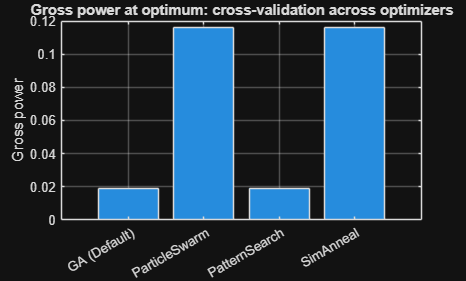

point   = [0, 0, 3, 0, 0, 0];   
wrench  = [0, 0, -2, 0, 0, 0];   
seg2Weight = [0, 0, -2000, 0, 0, 0]; 
comparison(point, wrench, seg2Weight, radii, lHome, lowLim, highLim, nvars, optionsDefault);

## Test Case 5B

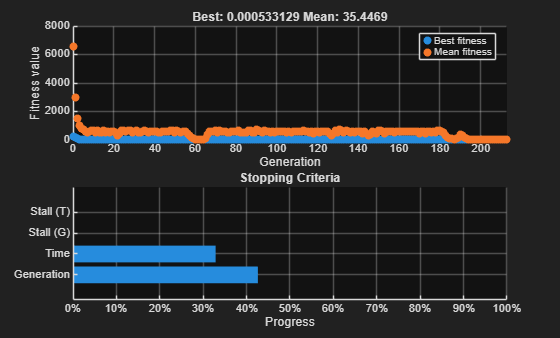

mid-plate pose:   [0 0 1.25 0 0 0]
stage-1 links:    [1.3379 1.3379 1.3379 1.3379 1.3379 1.3379]
stage-2 links:    [1.8014 1.8014 1.8014 1.8014 1.8014 1.8014]
gross power (minimized): 0.0005

--- Alternative Optimizer Validation ---
                          x          y          z       roll      pitch        yaw
GA (custom):     [0 0 1.25 0 0 0]
ParticleSwarm:   [0 0 1.25 0 0 0]
PatternSearch:   [0 0 1.25 0 0 0]
SimAnneal:       [0 0 1.25 0 0 0]

                    Gross power      Net power
GA (custom):           0.000533      -0.000000
ParticleSwarm:         0.000000      -0.000000
PatternSearch:         0.000533      -0.000000
SimAnneal:             0.000000       0.000000



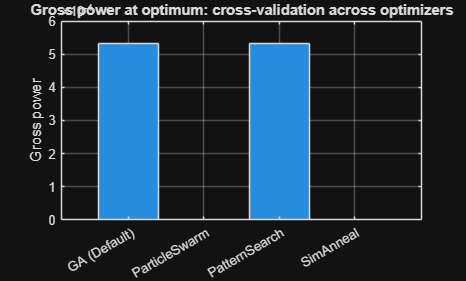

point   = [0, 0, 3, 0, 0, 0];   
wrench  = [0, 0, -2000, 0, 0, 0];   
seg2Weight = [0, 0, -2, 0, 0, 0]; 
comparison(point, wrench, seg2Weight, radii, lHome, lowLim, highLim, nvars, optionsDefault);

## Test Case 6

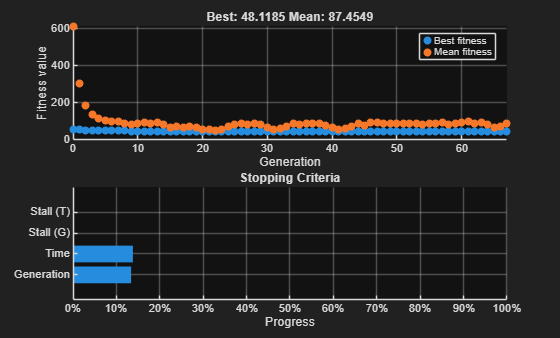

mid-plate pose:   [0.3237 0.4305 1.2697 -0.0951 0.2175 0.3477]
stage-1 links:    [1.3379 1.3379 1.6222 1.5669 1.3385 1.5567]
stage-2 links:    [2.16 1.8721 1.9517 2.0587 1.8263 2.0685]
gross power (minimized): 48.1185

--- Alternative Optimizer Validation ---
                          x          y          z       roll      pitch        yaw
GA (custom):     [0.3237 0.4305 1.2697 -0.0951 0.2175 0.3477]
ParticleSwarm:   [0.3166 0.4164 1.2725 -0.0939 0.2078 0.3523]
PatternSearch:   [0.3237 0.4305 1.2697 -0.0951 0.2175 0.3477]
SimAnneal:       [0.3166 0.4164 1.2725 -0.0939 0.2078 0.3523]

                    Gross power      Net power
GA (custom):          48.118485      22.201871
ParticleSwarm:        48.134753      21.876645
PatternSearch:        48.118485      22.201871
SimAnneal:            48.134753      21.876645



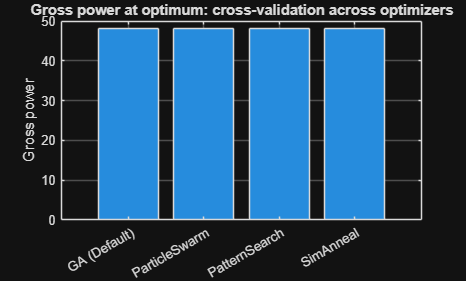

point   = [1, 1, 3, 0, 0, 0];   
wrench  = [0, 0, -50, 0, 0, 0];   
seg2Weight = [0, 0, -20, 0, 0, 0]; 
comparison(point, wrench, seg2Weight, radii, lHome, lowLim, highLim, nvars, optionsDefault);